# Figure 4F

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A029_data.mat'],'S','settings','allIF');

conditions = settings.conditions


framesPerHr = 60/12;
 frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;


times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
   
    S(i).POI_realtime = S(i).POI/framesPerHr;

end


**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

4F

conds=[1 13 3 15] ; 
colors = [.5 .5 .5 ;.1 .4 1;  .6 .9 .2;.9 .4 .2];

linetype = {'-','--','-','--'};
timeGate = [0 10];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).goodCdk & S(conds(i)).crlGate& S(conds(i)).apcExpressGate &S(conds(i)).cdkHighGate ;
    sum(inds)

ydata = nansmooth(S(conds(i)).cdk(inds,:),3);
    % ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;

    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',2,'linestyle',linetype(i)});
end

ans = 862

ans = 883

ans = 781

ans = 668

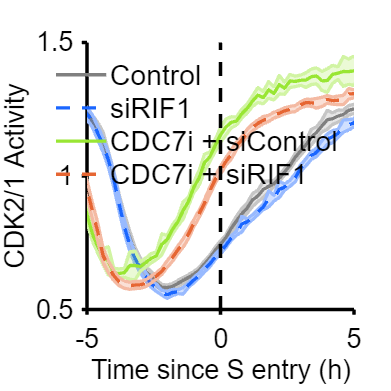


ylabel({'CDK2/1 Activity'});xlabel('Time since S entry (h)');
legend('Control','siRIF1','CDC7i + siControl','CDC7i + siRIF1','box','off','Location','north','fontsize',17);

xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')

 % print_pdf(['fig_4f.pdf'])